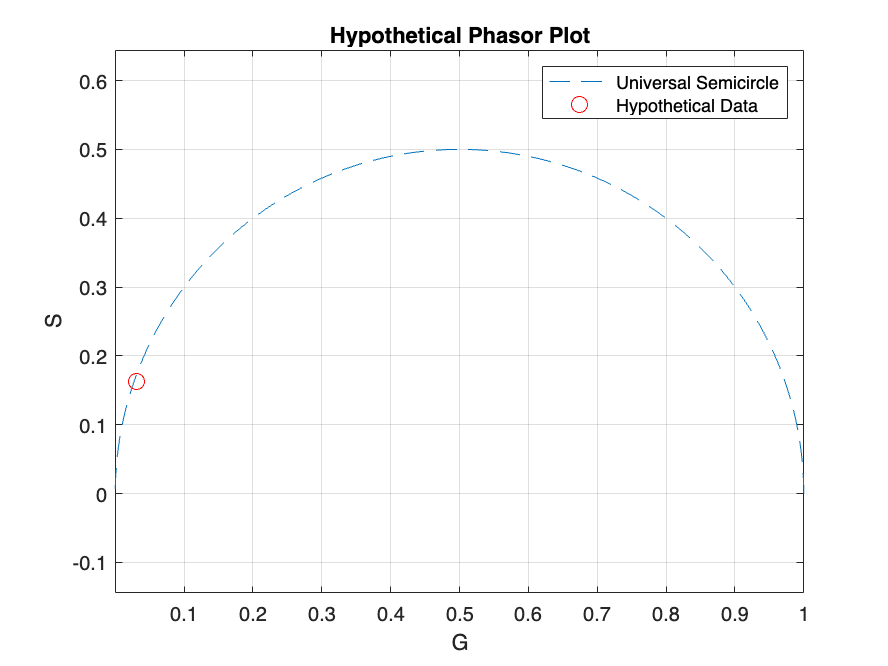

%simulate time-resolved fluorescence decay and convert to phasor point

%lifetime components (ns)
tau1 = 4.362;
tau2 = 5.0418;

%weights for each decay (should sum to ~1)
alpha1 = 0.80737;
alpha2 = 0.19263;

%modulation freq (approx. inverse of avg lifetime)
modFreq = 1 / ((tau1 + tau2) / 2);

%angular freq (ω = 2πf)
omega = 2 * pi * modFreq;

%time axis (0 to 20 ns, 0.01 step)
t_max = 20;
t_step = 0.01;
time = 0:t_step:t_max;

%simulated intensity = weighted sum of two decays
I_synthetic = alpha1 * exp(-time / tau1) + alpha2 * exp(-time / tau2);

%phasor coordinates from Fourier transform
G_synthetic = sum(I_synthetic .* cos(omega * time)) / sum(I_synthetic); %x
S_synthetic = sum(I_synthetic .* sin(omega * time)) / sum(I_synthetic); %y

%universal semicircle (for single-exponential reference)
theta = linspace(0, pi, 1000);
semicircleG = 0.5 + 0.5 * cos(theta); %x-values
semicircleS = 0.5 * sin(theta);      %y-values

%plotting
figure;
plot(semicircleG, semicircleS, '--', 'DisplayName', 'Universal Semicircle');
hold on;
plot(G_synthetic, S_synthetic, 'ro', 'MarkerSize', 8, 'DisplayName', 'Hypothetical Data');

%labels and formatting
title('Hypothetical Phasor Plot');
xlabel('G');
ylabel('S');
legend('show');
axis equal;
grid on;